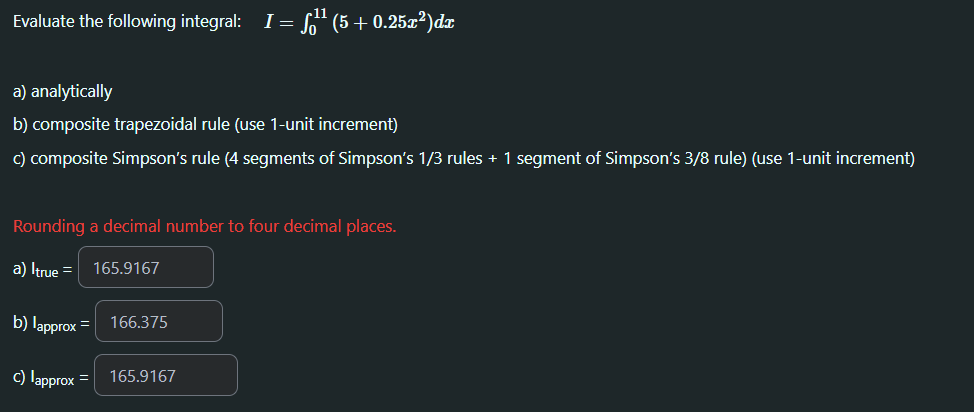

f = @(x) 5+0.25.*x.^2;

a = 0;
b = 11;

p = [ 0.25 0 5 ];
q = polyint(p);
Itrue = diff(polyval(q, [a,b]))

Itrue = 165.9167


Itrap = trap(f,a,b,11)

Itrap = 166.3750


ns = 4;
x = linspace(a,8.8,2*ns+1);
[I1_18,Ia] = simpson13(f,x,ns);
ns = 1;
x = linspace(8.8,b,3*ns+1);
[I2_38,Ib] = simpson38(f,x,ns);

Iest = I1_18 + I2_38

Iest = 165.9167

function [total,I] = simpson13(f,x,ns)
   
    total = 0;

    for i = 1:ns
        
        il = 2*(i-1)+1;
        ir = 2*i+1;
    
        newx = x(il:ir);
    
        h  =  (newx(1)-newx(3)) / 2 ; 
    
        I(i) = h/3 * ( f(newx(3)) + 4 .* f(newx(2)) + f(newx(1)) );
      
        total = total + I(i);
    
    end
    
    total = abs(total);
    I = abs(I);

end

function [total,I] = simpson38(f,x,ns)

total = 0;

for i = 1:ns

    il = 3*(i-1)+1;
    ir = 3*i+1;

    newx = x(il:ir);

    h = ( newx(1) -  newx(4) ) / 3;
    
    I(i) = 3*h/8 * ( f(newx(4)) + f(newx(2)) .* 3 + f(newx(3)) .* 3 + f(newx(1)) );
    total = total + I(i);

end
total = abs(total);
I = abs(I);
end
